# **pEllipticE**

Legendre form of the elliptic integral of the second kind 

## Definition


$$E\left(\phi \left|m\right.\right)\equiv \int_0^{\phi } \sqrt{1-m\;\sin^2 \theta }\;d\theta$$



$$E\left(\phi ,k\right)\equiv E\left(\phi \left|k^2 \right.\right)$$


where $\phi \;$is the argument, *k *is the modulus,  *m *is the parameter.

Domain: $1-m{\;\sin }^2 \phi \ge 0$ . If $-\infty <m\le 1$ (or $|k|\le 1$) then $-\infty \le \phi \le \infty$. If $m>1$ (or $k>1$) then  $\left|\phi \right|<{\mathrm{sin}}^{-1} \left(1/\sqrt{m}\right)\;$. For the specified domain, the  codomain is the set of real numbers.

Basic features:

$E\left(-\phi \left|m\right.\right)=-E\left(\phi \left|m\right.\right)$   (odd)

 $E\left(\textrm{n}\pi \pm \phi \left|m\right.\right)=2n\;E\left(m\right)\pm E\left(\phi \left|m\right.\right),\;\;\;\left|\phi \right|\le \pi /2$  (quasi-periodic)

Special values:

$E\left(0\left|m\right.\right)=0$,   $E\left(\frac{\pi }{2}\left|m\right.\right)=E\left(m\right)$

$E\left(\phi |-\infty \right)=0$,    $E\left(\phi \left|0\right.\right)=\phi$,  $E\left(\phi \left|1\right.\right)=\mathrm{sin}\left(\phi \right)$

Identities:

$E\left(\phi \left|m\right.\right)=E\left(\sin \left(\phi \right)\left|m\right.\right),\;\;\;\;\left|\phi \right|\le \pi /2$,     $E\left(\phi \left|m\right.\right)=\epsilon \left({\mathrm{am}}^{-1} \left(\phi \right)\left|m\right.\right)$

## Syntax

Y = pEllipticE(PHI,K)

y = pelE(phi,k)

Y = mpEllipticE(PHI,M)

y = mpelE(phi,m)

## Description

**Y = pEllipticE(PHI,K)** returns the Legendre form of elliptic integral of the second kind $E\left(\phi ,k\right)$ for each element of the arrays PHI (the argment) and K (the modulus). PHI and K must be real and the same size or any of them can be scalar. **pEllipticE** is the wrapper function which calls the functions **pelE** element-wise via the function **ufun2**.

**y = pelE(phi,k)** returns the value of  the Legendre form of elliptic integral of the second kind   $E\left(\phi ,k\right)$ for the argument phi and the modulus k. It is assumed that  the input arguments are real scalars without check. y is NaN if any of   the input arguments is invalid or convergence failed. **pelE** is the wrapper function which calls the functions **mpelE**.

**Y = mpEllipticE(PHI,M)** returns the Legendre form of elliptic integral of the first kind  $E\left(\phi \left|m\right.\right)$ for each element of the arrays PHI (the argument) and M (parameter). PHI and M must be real and the same size or any of them can be scalar. **mpEllipticE** is the wrapper function which calls the functions **mpelE** element-wise via the function **ufun2**.

**y = mpelE(phi,m)** returns the value of the Legendre form of elliptic integral of the first kind $F\left(\phi \left|m\right.\right)$ for  the argument phi and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mpelE **call the Bulrisch's function **el2 **for calculation of $E\left(\phi \left|m\right.\right)$ ([1]).

## Precision

For  ${10}^{-4} <m<{10}^4$ the relative error of **mpelE** is less than ${10}^{-12}$ when $\left|x\right|<{10}^4$.

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
phi = pi/6;
[pelE(phi,k), pEllipticE(phi,k), mpelE(phi,k^2), mpEllipticE(phi,k^2)]

ans =    0.517881934859938   0.517881934859938   0.517881934859938   0.517881934859938


Accuracy. 

fprintf('%.16g\n',pelE(pi/4,1/2)) % Maple 18D  =  0.7671959857111226 78

0.7671959857111227


Special values

m = 0.5;
phi = pi/9;
mpEllipticE(-phi,m) + mpEllipticE(phi,m)  % asymmetry

ans = 0

mpEllipticE(0,m)

ans = 0

disp(mpEllipticE(pi/2,m) - mEllipticE(m))

     0



disp(pEllipticE(phi,0) - phi)

     0



disp(pEllipticE(phi,1) - sin(phi))  

     0



Identities

m=-10^4;
phi = 0.499*pi; % |phi|<=pi/2
disp(mpelE(phi,m) - melE(sin(phi),m))

    -1.506350599811412e-12



disp(mpelE(phi,m) - mjepsilon(mijam(phi,m),m))

     2.017941369558685e-12



k = 0.99995; % |k|<1
disp(pEllipticE(asin(1/sqrt(1+sqrt(1-k^2))),k) - (elE(k) + 1 - sqrt(1 - k^2))/2)

     1.110223024625157e-16



phi = pi/3; % |phi|<=pi/2
k = 0.5; % |k|<=1
n = 2;
disp(pelE(phi+n*pi,k)-(pelE(phi,k)+2*n*elE(k))) % periodicity

     0



**Vector input**

format short
k = 0.5;
PHI = [pi/3, pi/4, 1, pi/2];
disp(pEllipticE(PHI,k) - EllipticE(sin(PHI),k))

   1.0e-15 *

         0    0.2220         0         0



**Matrix input**

Test identity $E\left(\phi \left|m\right.\right)=\mathit{\mathbf{E}}\left(\sin \left(\phi \right)\left|m\right.\right),\left|\phi \right|\le \pi /2$

PHI = [pi/6 pi/4 3*pi/8; -pi/6 -pi/4 -3*pi/8];
M = [1/4 1 1/9; -0.1 0.2 0.1];
disp(mpEllipticE(PHI,M) - mEllipticE(sin(PHI),M))

   1.0e-15 *

    0.2220         0    0.4441
   -0.2220    0.1110   -0.2220



## **Graphs **

**Example 1**

[MATLAB example](https://www.mathworks.com/help/symbolic/elliptice.html)

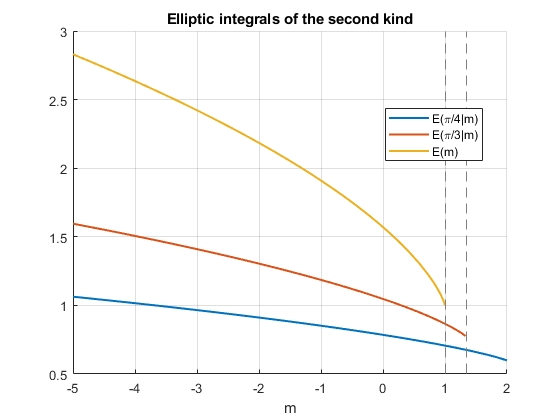

figure
hold on
fplot(@(m)mpEllipticE(pi/4, m),'LineWidth',1.5)
fplot(@(m)mpEllipticE(pi/3, m),'LineWidth',1.5)
fplot(@(m)mEllipticE(m),'LineWidth',1.5)
xlabel('m')
grid on
title('Elliptic integrals of the second kind')
legend('E(\pi/4|m)', 'E(\pi/3|m)', 'E(m)', 'Location', 'Best')
hold off

**Example 2**

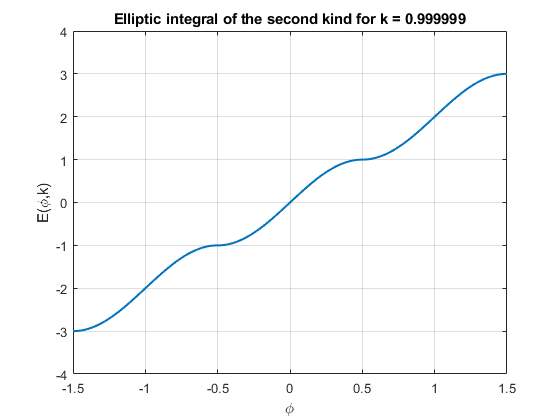

figure
phi=-1.5:0.01:1.5;
k = 0.999999;
plot(phi,pEllipticE(pi*phi,k),'LineWidth',1.5)
xlabel('\phi')
ylabel('E(\phi,k)')
%xlim([-1.1 1.1])
%ylim([-3 3])
title(sprintf('Elliptic integral of the second kind for k = %g',k))
grid on

**Example 3**

figure
PHI = -2:0.01:2;
M = [-1,0,0.9, 1,1.5];
SN = zeros(length(M),length(PHI));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mpEllipticE(pi*PHI,M(i));
end
plot(PHI,SN,'LineWidth',1.5)
axis([min(PHI) max(PHI) -5 5])
grid on
legend(clg,'Location','Best')

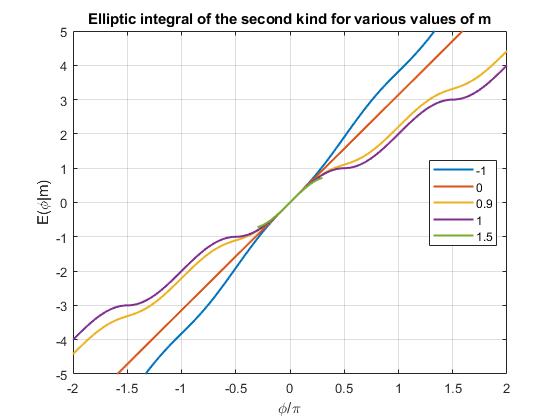

title('Elliptic integral of the second kind for various values of m')
xlabel('\phi/\pi')
ylabel('E(\phi|m)')

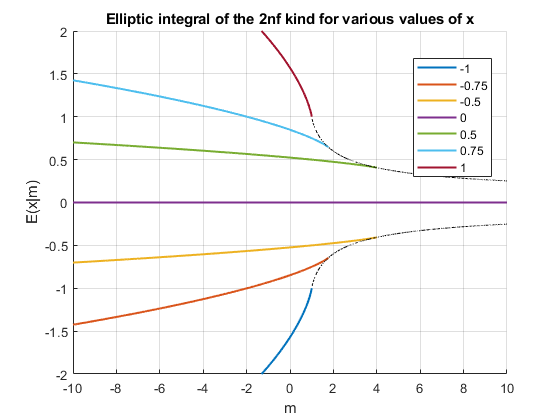

figure
hold on
M = -10:0.01:10;
X = [-1,-0.75,-0.5,0,0.5,0.75,1];
SN = zeros(length(X),length(M));
clg{length(X)}=[];
for i = 1:length(X)
     clg{i} = num2str(X(i));
    SN(i,:) = mEllipticE(X(i),M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -2 2])
M = 0:0.01:10;
E = mEllipticE(1./sqrt(abs(M)),M);
plot(M,E,'k-.')
plot(M,-E,'k-.')
grid on
legend(clg{1:length(X)},'Location','Best')
title('Elliptic integral of the 2nf kind for various values of x')
xlabel('m')
ylabel('E(x|m)')
hold off

**Example 4**

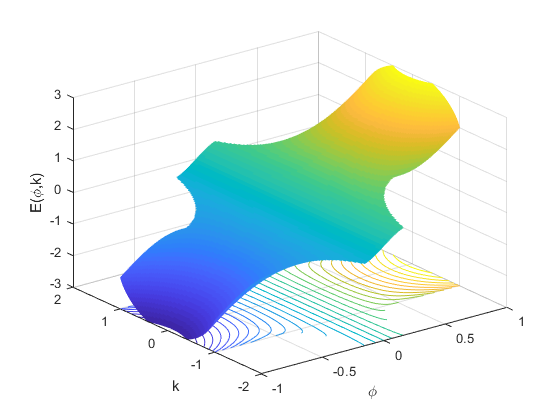

figure
phi=-1:0.01:1;
k=-2:0.01:2;
[PHI,K]=meshgrid(phi,k);
hs=surfc(PHI,K,pEllipticE(pi*PHI,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -3;
hc.LineWidth = 0.5;
hc.LevelList = -3:0.2:3;
caxis([-3 3])
view(3);
xlabel('\phi')
ylabel('k')
zlabel('E(\phi,k)')
zlim([-3 3])
grid on

**Example 5**

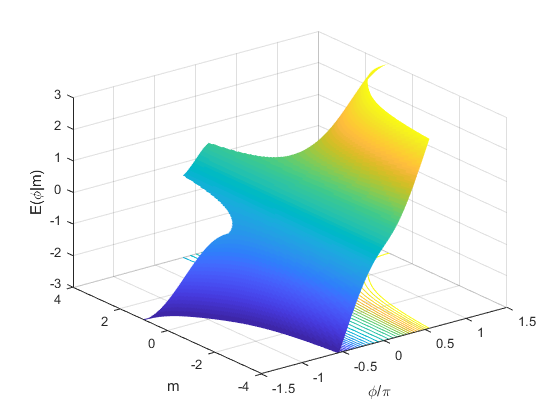

figure
phi=-1.5:0.01:1.5;
m=-4:0.01:4;
[PHI,M]=meshgrid(phi,m);
hs=surfc(PHI,M,mpEllipticE(pi*PHI,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -3;
hc.LineWidth = 0.5;
hc.LevelList = -3:0.2:3;
view(3)
caxis([-3 3])
xlabel('\phi/\pi')
ylabel('m')
zlabel('E(\phi|m)')
zlim([-3 3])
grid on

**Example 6**

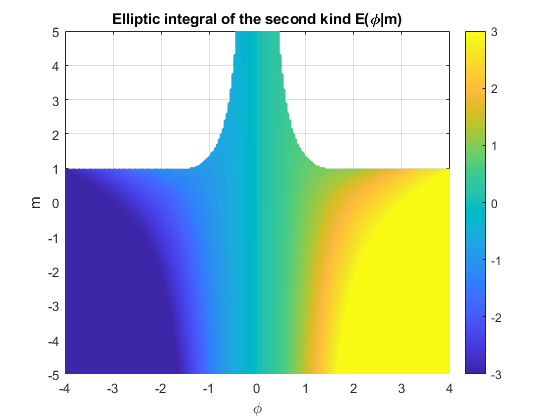

figure
f = @(phi,m)mpEllipticE(phi,m);
fcontour(f,[-4 4 -5 5],'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Elliptic integral of the second kind E(\phi|m)')
colorbar
xlabel('\phi')
ylabel('m')
grid on

**Example 7**

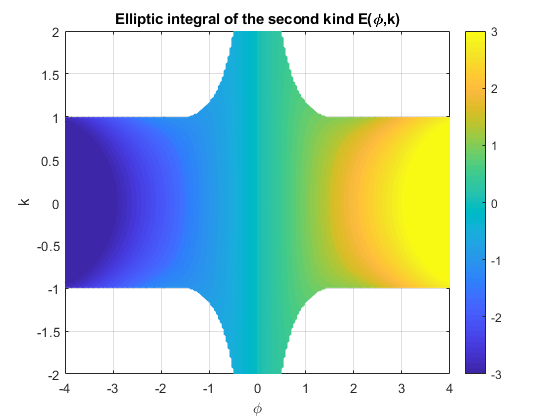

figure
f = @(phi,k)pEllipticE(phi,k);
fcontour(f,[-4 4 -2 2],'Fill','on','LevelList',-3:0.1:3,'MeshDensity',200)
title('Elliptic integral of the second kind E(\phi,k)')
colorbar
xlabel('\phi')
ylabel('k')
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

## **References**

[1] R. Bulirsch, Numerical Calculation of Elliptic Integrals and Elliptic Functions. Numerische Mathematik 7, 78-90, 1965

## See Also